clear variables;

x = 1:5;
y = normrnd(4, 1, 1, 5);

f1 = fit(x', y', 'exp1')

f1 =      General model Exp1:
     f1(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       3.263  (0.6929, 5.834)
       b =     0.06144  (-0.1615, 0.2844)

f2 = fit(x', y', 'fourier1')

f2 =      General model Fourier1:
     f2(x) =  a0 + a1*cos(x*w) + b1*sin(x*w)
     Coefficients (with 95% confidence bounds):
       a0 =       3.879  (-0.9197, 8.677)
       a1 =      0.9472  (-5.546, 7.44)
       b1 =      0.1226  (-13.85, 14.1)
       w =       1.394  (-3.511, 6.299)

f3 = fit(x', y', 'gauss1')

f3 =      General model Gauss1:
     f3(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =  1.155e+157  (-Inf, Inf)
       b1 =   1.173e+04  (-1.397e+09, 1.397e+09)
       c1 =         618  (-3.679e+07, 3.679e+07)

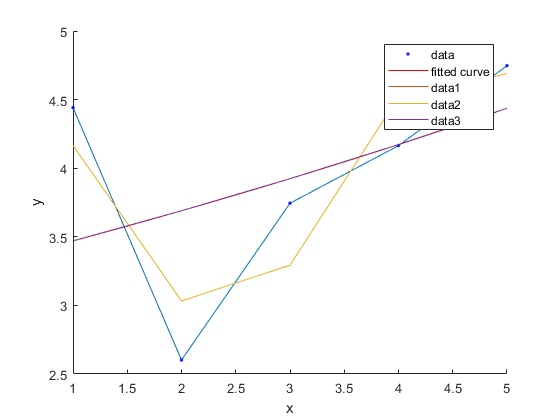


y_apr_1 = f1.a * exp(f1.b * x);
y_apr_2 = f2.a0 + f2.a1 * cos(x * f2.w) + f2.b1 * sin(x * f2.w);
y_apr_3 = f3.a1 * exp(-((x - f3.b1)/f3.c1).^2);

hold on;
plot(x, y);
plot(f1, x, y);
% plot(f2, x, y);
% plot(f3, x, y);
plot(x, y_apr_1);
plot(x, y_apr_2);
plot(x, y_apr_3);
hold off;